# Stima ML dei parametri di una Poisson generalizzata

Si propone un'implementazione di un algoritmo per la stima dei parametri caratteristici della distribuzione Poisson generalizzata.

### Problemi ed obiettivi

Il problema consiste nella stima della media e del parametro di forma (o dispersione). Per la verifica della correttezza dell'algoritmo si userà il MSE. Verranno utilizzati dei dati prodotti sinteticamente.

### Motivazioni

Si cerca una stima del parametro di intensità (tasso di arrivo) fondamentale nel calcolo della probabilità di blocco e dunque nel design/dimensionamento di un sistema.  Si è scelta una Poisson generalizzata invece di una Gaussiana generalizzata, in quanto affermare che i processi seguano una distribuzione di Poisson equivale ad affermare che il mio sistema venga eccitato da un flusso di pacchetti che segue un processo di conteggio. Questa prima ipotesi descritta è di fondamentale importanza, in quanto se utilizzassi una Gaussiana Generalizzata (GG) avrei due problemi:

- Il parametro di forma non è ricavabile in forma chiusa e gli stimatori ML dei vari parametri non sono banali da ricavare

- Perdo completamente la struttura del problema sottostante, quindi ho una modellazione probabilistica corretta (stimo correttamente i parametri della GG) ma ho perso la struttura di processo di conteggio allontanandomi "dalla realtà"

Per questi motivi ho scelto una Poissoniana Generalizzata. Come effetto collaterale si può osservare che una estensione della Poissoniana mi permette di accomodare quei casi in cui il flusso dei pacchetti è *all'incirca* di tipo poissoniano, cioè ho sempre un processo di conteggio ma non è perfettamente poissoniano. A causa di questo "mismatch" non sarebbe corretto definire il tasso di arrivo come la media della distribuzione. Inserendo una generalizzazione tramite il parametro di forma riesco a rilassare questo requisito e ottenere comunque una definizione di tasso di arrivo corretta. Si osserva che la definizione di $\lambda$ è corretta in quanto funzione della media della distribuzione e rettificata grazie al fattore di forma $\alpha$. Altrimenti potrei procedere con un approccio classico e modellare questo mismatch come rumore e procedere con una ricerca di una costante immersa in rumore WGN. Si seguirà il primo metodo, poiché più elegante.

Consul e Shoukri [1] discussero il problema dell'esistenza di uno stimatore ML per i parametri della Poissoniana generalizzata, dimostrando una condizione necessaria e sufficiente alla convergenza numerica della soluzione. Non useremo qui la loro notazione.

### Ipotesi

Il parametro incognito intensità della Poissoniana generalizzata è deterministico, dunque usiamo un approccio frequentista. L'altro parametro, cioè il parametro di dispersione, si ipotizza sia incognito ma appertenente all'intervallo $\left\lbrack 0\;,1\right\rbrack$. In cui 0 è una poisson classica ed 1 il modello è completamente sbagliato, non ho una distribuzione di Poisson.

Non si ipotizzano cluster di flussi, cioè esistono più flussi ma vengono tutti trattati alla stessa stregua, sto studiando un sistema (come ad esempio un firewall) che si vede arrivare dei flussi ed ancora non ha ispezionato i pacchetti.

### Modello matematico

Chiamiamo la distribuzione discreta di probabilità Generalized Poisson la seguente pmf:


$$p\left(X=x\left|\lambda ,\alpha \right.\right)\left\lbrace \begin{array}{ll}
\frac{\lambda {\left(\lambda +\alpha x\right)}^{x-1} e^{-\left(\lambda +\alpha x\right)} }{x!} & x=0,1\ldotp \ldotp \ldotp ,\lambda \;,\;0<\alpha <1\\
0 & \textrm{altrimenti}
\end{array}\right.$$


Dove $E\left\lbrace X\right\rbrace =\frac{\lambda }{1-\alpha }$ inoltre $\textrm{var}\left(X\right)=\frac{\lambda }{{\left(1-\alpha \right)}^3 }$ 

Si osserva che se $\alpha =0$ allora otteniamo una Poisson classica. Per la stima dei parametri della pmf sia $\underline{X} =\left\lbrace x_0 ,x_2 ,{\;x}_3 ,\cdots ,x_{N-1} \right\rbrace$la sequenza di campioni raccolti di dimensione $N$.

### Descrizione dell'algoritmo

La log likelihood function è data dal logaritmo naturale della funzione di verosimiglianza congiunta per tutto il vettore di campioni $\underline{X}$. Nell'ipotesi di campioni distribuiti in modo iid ottengo:

 
$$p\left(\underline{X} ;\lambda ,\alpha \right)=\;$$

$$\prod_{i=0}^{N-1} \frac{\lambda {\left(\lambda +\alpha x\left\lbrack i\right\rbrack \right)}^{x\left\lbrack i\right\rbrack -1} e^{-\left(\lambda +\alpha x\left\lbrack i\right\rbrack \right)} }{x\left\lbrack i\right\rbrack !}$$
 

La funzione di log-likelihood:


$$\ln \left(\prod_{i=0}^{N-1} \frac{\lambda }{x\left\lbrack i\right\rbrack !}{\left(\lambda +\alpha x\left\lbrack i\right\rbrack \right)}^{x\left\lbrack i\right\rbrack -1} e^{-\left(\lambda +\alpha x\left\lbrack i\right\rbrack \right)} \right)=\sum_{i=0}^{N-1} \ln \left(\frac{\lambda }{x\left\lbrack i\right\rbrack !}{\left(\lambda +\alpha x\left\lbrack i\right\rbrack \right)}^{x\left\lbrack i\right\rbrack -1} e^{-\left(\lambda +\alpha x\left\lbrack i\right\rbrack \right)} \right)$$



$$\ln \left(p\left(\underline{X} ;\lambda ,\alpha \right)\right)=\sum_{i\;=\;0}^{N-1} \ln \left(\frac{\lambda }{x\left\lbrack i\right\rbrack !}\right)+\sum_{i\;=\;0}^{N-1} \left(x\left\lbrack i\right\rbrack -1\right)\ln \left(\lambda +\alpha x\left\lbrack i\right\rbrack \right)-\sum_{i=0}^{N-1} \left(\lambda +\alpha x\left\lbrack i\right\rbrack \right)$$


Ciò che cerco di ottenere è il seguente vettore:

$\left\lbrack \begin{array}{c}
\frac{\partial }{\partial \lambda }\ln \left(p\left(\underline{X} ;\lambda ,\alpha \right)\right)=0\\
\frac{\partial }{\partial \alpha }\ln \left(p\left(\underline{X} ;\lambda ,\alpha \right)\right)=\;0
\end{array}\right\rbrack$= $\left\lbrack \begin{array}{c}
\lambda^ˆ =\left(1-\alpha^ˆ \right)\bar{x} \\
\sum_{i=0}^{N-1} \frac{x\left\lbrack i\right\rbrack \left(1-x\left\lbrack i\right\rbrack \right)}{\bar{x} \left(x\left\lbrack i\right\rbrack -\bar{x} \right)\alpha^ˆ }-N\bar{x} =0\;
\end{array}\right\rbrack$

Possiamo osservare come per la stima del parametro di dispersione $\alpha$ non esista una forma chiusa. Si deve necessariamente ricorrere ad una soluzione numerica. La via seguita è quella del metodo iterativo di Newton-Raphson. Di fondamentale importanza è la scelta del punto di innesco del metodo. Inizio la ricerca del parametro $\alpha$ a partire da 0.5 un valore che permette di terminare in tempi ragionevoli tutte le simulazioni. 

### Implementazione dell'algoritmo

Dal sistema delle equazioni si osserva che il parametro $\lambda$ è funzione di $\alpha$. Esso è ricavabile in forma chiusa ed è separabile in due sottoproblemi, dunque ci concentriamo sul parametro di dispersione. Utilizzando il metodo di newton Raphson ottengo:


$$g\left(\alpha \right)\approx g\left(\alpha_0 \right)+\frac{d\left(g\left(\alpha \right)\right)}{d\alpha }\;\left(\alpha -\alpha_0 \right)\;$$
 

Pongo $g\left(\alpha \right)=0$ poiché cerco gli zeri dell'equazione


$$g\left(\alpha \right)=$$

$$\sum_{i=0}^{N-1} \frac{x\left\lbrack i\right\rbrack \left(1-x\left\lbrack i\right\rbrack \right)}{\bar{x} \left(x\left\lbrack i\right\rbrack -\bar{x} \right)\alpha^ˆ }-N\bar{x}$$


dove il parametro $\bar{x} =\frac{1}{N}\sum_{i=0}^{N-1} x\left\lbrack i\right\rbrack \;$ è la media campionaria.

Proseguo e ottengo:


$$\sum_{i=0}^{N-1} \frac{x\left\lbrack i\right\rbrack \left(1-x\left\lbrack i\right\rbrack \right)}{\bar{x} \left(x\left\lbrack i\right\rbrack -\bar{x} \right)\alpha^ˆ }-N\bar{x} =0$$



$$\frac{\textrm{dg}\left(\alpha \right)}{d\alpha }=\sum_{i=0}^{N-1} \frac{d}{d\alpha }\left\lbrace \frac{\left(x\left\lbrack i\right\rbrack \left(x\left\lbrack i\right\rbrack -1\right)\right)}{\bar{x} \left(x\left\lbrack i\right\rbrack -\bar{x} \right)\alpha^ˆ }\right\rbrace =-\frac{x\left\lbrack i\right\rbrack \left(x\left\lbrack i\right\rbrack -1\right)\left(x\left\lbrack i\right\rbrack -\bar{x} \right)}{{\left(\bar{x} +\left(x\left\lbrack i\right\rbrack -\bar{x} \right)\alpha^ˆ \right)}^2 }$$


Rimettendo tutto insieme ottengo per un generico $\alpha_k$


$$\hat{\alpha_{k+1} } =\hat{\alpha_k } -\frac{\sum_{i=0}^{N-1} \frac{x\left\lbrack i\right\rbrack \left(x\left\lbrack i\right\rbrack -1\right)}{\bar{x} +\left(x\left\lbrack i\right\rbrack -\bar{x} \right)\hat{\alpha_k } }-N\bar{x} }{-\sum_{i=0}^{N-1} \frac{x\left\lbrack i\right\rbrack \left(x\left\lbrack i\right\rbrack -1\right)\left(x\left\lbrack i\right\rbrack -\bar{x} \right)}{{\left(\bar{x} +\left(x\left\lbrack i\right\rbrack -\bar{x} \right)\hat{\alpha_k } \right)}^2 }}$$


Dunque bisogna implementare questa equazione per la ricerca delle soluzioni dell'espressione $\frac{\partial }{\partial \alpha }\ln \left(p\left(\underline{X} ;\lambda ,\alpha \right)\right)=\;0$

Si veda in appendice per l'implementazione con codice Matlab.

### Simulazione

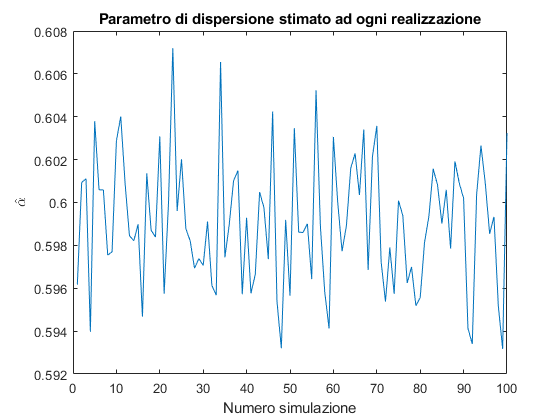

lambda = 14;
alpha = 0.6;
% simulazione Montecarlo
K = 100;  % numero di esperimenti
alpha_hat=[];
lambda_hat=[];
for k=1:K
    x = gpoissrnd(lambda, alpha, 10000);
    alpha_hat(k) = ML_estimator(x);
    lambda_hat(k)=(1-alpha_hat(k))*mean(x);
end
plot(alpha_hat)
title('Parametro di dispersione stimato ad ogni realizzazione')
xlabel('Numero simulazione')
ylabel('$$\hat{\alpha}$$','Interpreter','Latex')

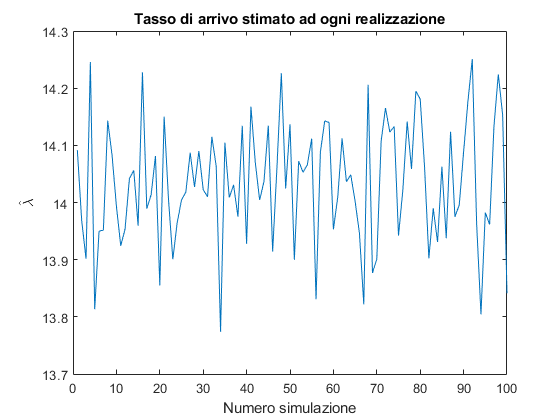

plot(lambda_hat)
title('Tasso di arrivo stimato ad ogni realizzazione')
xlabel('Numero simulazione')
ylabel('$$\hat{\lambda}$$','Interpreter','Latex')

Osserviamo come la media calcolata fra tutte le 100 simulazioni prodotte si avvicini (in genere) fino alla 4 cifra significativa. Con un MSE dell'ordine di 1.e-5.

media_dispersione = mean(alpha_hat)

media_dispersione = 0.5991

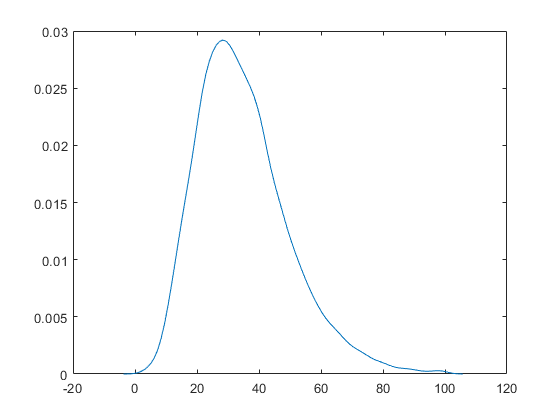

ksdensity(x)

MSE_dispersione = (sum(alpha_hat-alpha)^2)/length(alpha_hat)

MSE_dispersione = 8.9969e-05

Per il tasso di arrivo:

media_intensita = mean(lambda_hat)

media_intensita = 14.0338

MSE_intensita = (sum(lambda_hat-lambda)^2)/length(lambda_hat)

MSE_intensita = 0.1145

### Problematiche di convergenza e discussione delle prestazioni

La risoluzione mediante il metodo di Newton Raphson per la ricerca dello zero , porta con se diversi problemi di convergenza. La funzione è in generale decrescente con una pendenza piuttosto elevata come in questo esempio:

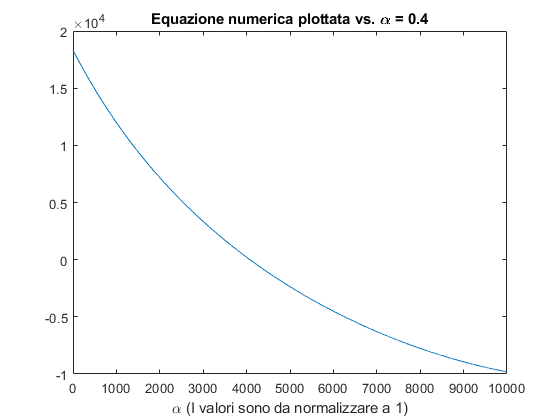

alpha=linspace(0,1,10000);
y=gpoissrnd(4,0.4,10000);
ordinata=[];
mean_y=mean(y);
for i=1:10000
    ordinata(i)=sum( (y .* (y-1)) ./ (mean_y + (y-mean_y)*alpha(i))) - length(y)*mean_y;
end
plot(ordinata)
title('Equazione numerica plottata vs. \alpha = 0.4')
xlabel('\alpha (I valori sono da normalizzare a 1)')

Si può osservare come vicino al valore 4000 (in realtà p da normalizzare ottenendo 0,4) vediamo che la funzione tocca il suo zero ed è monotona decrescente.

Spostando il parametro più vicino ad 1 la situazione peggiora drasticamente. Per valori vicini ad 1 la funzione tocca asintoticamente lo zero:

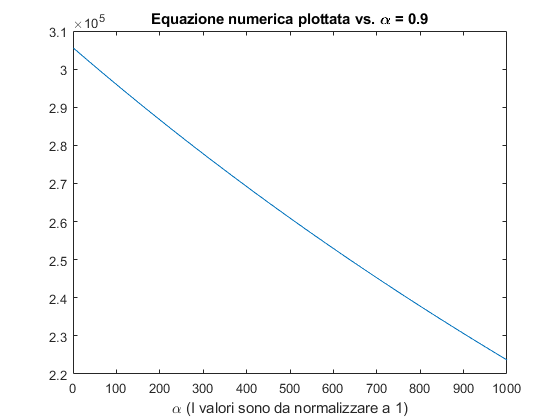

alpha=linspace(0,1,10000);
y=gpoissrnd(4,0.9,10000);
ordinata=[];
mean_y=mean(y);
for i=1:1000
    ordinata(i)=sum( (y .* (y-1)) ./ (mean_y + (y-mean_y)*alpha(i))) - length(y)*mean_y;
end
plot(ordinata)
title('Equazione numerica plottata vs. \alpha = 0.9')
xlabel('\alpha (I valori sono da normalizzare a 1)')

Questo purtroppo significa un aumento consistente dei tempi di calcolo e una riduzione della precisone. Il meglio che si può ottenere è un bias pari (in genere) al 30% del valore vero dopo circa 30s di calcolo (circa 70000 iterazioni).

Il problema è dovuto alla violazione delle ipotesi per la convergenza del metodo. Condizione necessaria e sufficiente affinché si abbia un'unica soluzione $\alpha_k$ fra 0 e 1 è:


$$\sum_{j=2}^k n_y \frac{x\left(x-1\right)}{\bar{x} +\left(x-\bar{x} \right)\alpha }-n\bar{y} >0$$
  

In questo caso si usa la pdf raggruppata cioè in funzione delle frequenze osservate, si veda l'articolo allegato per la dimostrazione. 

Nei casi in cui il mio parametro $\alpha >0\ldotp 75$ si ha un aumento nel MSE e nel bias dello stimatore. Questo si spiega grazie al problema della overdispersion. In sostanza il mio vettore dei dati viene comunque modellizzato come una Poissoniana, ma con un fattore di forma molto lontato dalla "vera poissonianità". Ciò ha come effetto che la varianza dei dati è molto maggiore della media. Questo lo si può verificare, oltre che calcolandosi media e varianza campionaria, tramite un fit semiparametrico con la function `ksdensity`, tanto più che mi avvicino ad 1 e tanto più che la curva non assomiglia ad una poissoniana. 

Possiamo analizzare questo degrado delle prestazioni al tendere di $\alpha \to 1$ facendo un plot del MSE associato al mio stimatore:

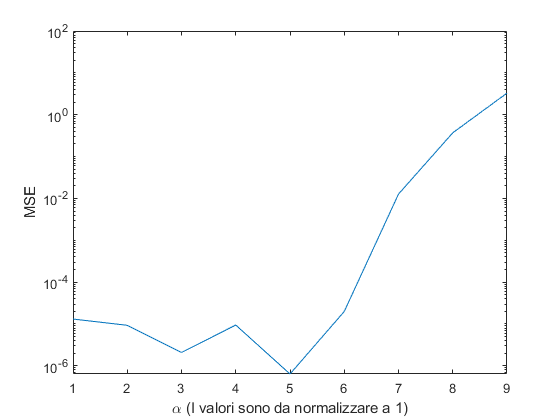

alpha_hat=[]; mse=[]; bias=[];
param= 0.1:0.1:0.9;             % grigliato di 9 punti
for k=1:length(param)           % per il plot al variare di alpha
    alpha = param(k);
    K = 100;    
    for j=1:K
        x = gpoissrnd(lambda, alpha, 10000);
        alpha_hat(j) = ML_estimator(x);
    end
    mse(k)=(sum(alpha_hat-alpha)^2)/length(alpha_hat);
    bias(k)=sum(alpha_hat-alpha)/length(alpha_hat);
end
semilogy(mse)
xlabel('\alpha (I valori sono da normalizzare a 1)')
ylabel('MSE')

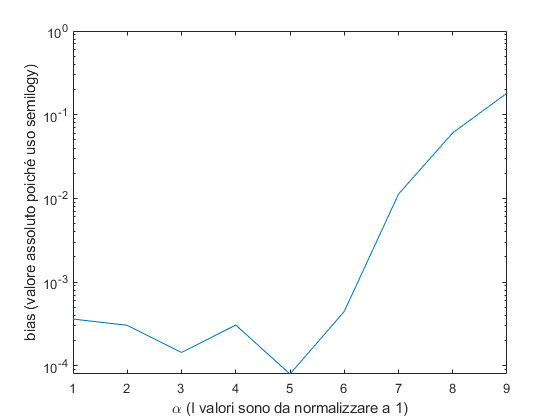

semilogy(abs(bias))
xlabel('\alpha (I valori sono da normalizzare a 1)')
ylabel('bias (valore assoluto poiché uso semilogy)')

### Appendice, codice matlab:

function [alpha_hat] = ML_estimator(x)
MAXiter_Newton = 70000;    %Criterio di arresto
mean_x =mean(x);
alpha0 = 0.5;
for k = 1:MAXiter_Newton
    numeratore = sum( (x .* (x-1)) ./ (mean_x + (x-mean_x)*alpha0)) - length(x)*mean_x;
    denominatore = -sum( (x.*(x-1).*(x - mean_x)) ./ (mean_x + (x - mean_x)*alpha0).^2);
    alpha = alpha0 - numeratore/denominatore;
    if abs(alpha-alpha0) < 1.e-12
        alpha_hat = alpha;
        return;
    else
        alpha0 = alpha;
    end   
end
alpha_hat = alpha;
end

% Credit: Comparison of methods of estimation for parameters of 
%         generalized Poisson distribution through simulation study 
%           Y.S.Wagh and K. K.Kamalja
% The function gpoissrnd() generates a random sample of size n from 
% Generalized Poisson distribution with parameters (lambda,a) 
% pmf of GPD(lambda,a) is used from: Consul and Jain (1973a) Consul and Jain (1973a),
% A generalization of the Poisson distributions,
% Technometrics, 15, 791–799.
% Parameters : parameter=lambda
%              dispersion parameter=a
% Moments of GPD:Mean=μ=lambda/(1-a),Variance=s2=
%f∗μ Note:f=1/(1-a)^2 is called as Dispersion factor of% GPD(lambda,a). 
%Simulation from GPD(lambda, a)
function [x]=gpoissrnd(lambda,alpha,n)
    phi=1/(1-alpha)^2;
    it=100;
    if length(lambda)==1
        mu=lambda/(1-alpha);
        p(1)=exp(-lambda);
        for i=1:it
            N=(lambda+alpha*i)^(i-1);
            D=((lambda+alpha*(i-1))^(i-2))*(i)*exp(alpha);
            if(N<Inf)
                p(i+1)=p(i)*N/D;
            else
                lp(i+1)=log(p(i))-(i-1)*log(lambda+alpha*i)+...
                    i*log(lambda+alpha*(i+1))-alpha-log(i+1);
                p(i+1)=exp(lp(i+1));
            end
        end
        cp=cumsum(p);
        for i=1:n
            x(i)=length(p(cp(1:it-1)<rand(1)<cp(2:it)==0));
        end
    else
        for i=1:length(lambda)
            x(i)=gpoissrnd(lambda(i),alpha,1);
        end
    end
end